% Short Molecular Clip with TFPT
%% NMR TITRATION MODEL — Host & Guest Dimerization, 1:1 Binding
clear; clc;

%% === INPUT SECTION ===
% Experimental total concentrations (mol/L)
Htot = [0.25, 1, 2, 3, 4 ,5, 6, 7.5]' * 1e-3; % Guest total conc. (in M)
Gtot = [0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5]' * 1e-3;      % Fixed Host total conc. (in M)

% Experimental guest chemical shift values (replace with real data)
delta_obs_exp = [8.8884, 8.8861, 8.883, 8.8801, 8.8764, 8.8738, 8.8709, 8.8666]'; %HOST
%delta_obs_exp = [10.1971, 10.1968, 10.1962, 10.1957, 10.1948, 10.1943, 10.1938, 10.1927]'; %GUEST
% Known dimerization constants
KG2 = 27; % Host dimerization (M^-1)
KH2 = 15.1; % Guest dimerization (M^-1)

%% === INITIAL GUESSES ===
% params = [log10(KHG), delta_G, delta_G2, delta_HG]
params0 = [2, 8.895, 8.89, 8.89];
lb = [-1, 5, 5, 5];      % lower bounds
ub = [10, 10.3, 10.3, 10.3];  % upper bounds

%% === FITTING ROUTINE ===
options = optimoptions('lsqcurvefit','Display','iter','TolFun',1e-9,'TolX',1e-9);
[params_fit,~,~,~,~,~,J] = lsqcurvefit( ...
    @(p,x) model_shift(p, x, KH2, KG2), ...
    params0, [Htot Gtot], delta_obs_exp, lb, ub, options);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          5        0.00230979                            0.353
     1         10       2.65693e-05       0.0390617            0.011      
     2         15       8.12101e-06       0.0784147           0.0039      
     3         20       8.12101e-06        0.183599           0.0039      
     4         25       6.89392e-06       0.0458996          0.00652      
     5         30       6.17781e-06       0.0458996          0.00811      
     6         35       4.74855e-06       0.0114749          0.00099      
     7         40       4.18649e-06       0.0229498         0.000764      
     8         45       4.02696e-06       0.0458996           0.0103      
     9         50       2.53112e-06       0.0114749         0.000705      
    10         55       2.33491e-06       0.0229498          0.00192      
    11         60       2.10836e-06      


% Confidence Intervals (optional)
%ci = nlparci(params_fit, [], 'jacobian', J);

%% === RESULTS ===
KHG = 10^params_fit(1);
delta_G   = params_fit(2);
delta_G2  = params_fit(3);
delta_HG  = params_fit(4);

fprintf('\nFitted Parameters:\n');


Fitted Parameters:


fprintf('K_HG (1:1 binding)   = %.2e M^-1\n', KHG);

K_HG (1:1 binding)   = 1.53e+00 M^-1


fprintf('delta_G   (free G)   = %.3f ppm\n', delta_G);

delta_G   (free G)   = 8.894 ppm


fprintf('delta_G2  (G dimer)  = %.3f ppm\n', delta_G2);

delta_G2  (G dimer)  = 8.742 ppm


fprintf('delta_HG  (HG complex)= %.3f ppm\n', delta_HG);

delta_HG  (HG complex)= 6.429 ppm


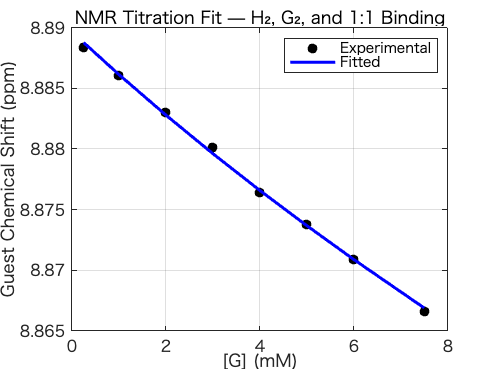


%% === PLOT ===
delta_fit = model_shift(params_fit, [Htot Gtot], KH2, KG2);

figure;
plot(Htot*1e3, delta_obs_exp, 'ko', 'MarkerFaceColor', 'k'); hold on;
plot(Htot*1e3, delta_fit, 'b-', 'LineWidth', 2);
xlabel('[G] (mM)'); ylabel('Guest Chemical Shift (ppm)');
legend('Experimental','Fitted');
title('NMR Titration Fit — H₂, G₂, and 1:1 Binding');
grid on;


% Calculate R-squared
SS_res = sum((delta_obs_exp - delta_fit).^2);
SS_tot = sum((delta_obs_exp - mean(delta_obs_exp)).^2);
R_squared = 1 - (SS_res / SS_tot);

% Display R-squared
fprintf('R-squared: %.6f\n', R_squared);

R-squared: 0.998637


function delta_obs = model_shift(params, xdata, KH2, KG2)
    KHG = 10^params(1); % 1:1 binding constant
    delta_G  = params(2);
    delta_G2 = params(3);
    delta_HG = params(4);

    Htot = xdata(:,1);
    Gtot = xdata(:,2);
    N = length(Htot);
    delta_obs = zeros(N,1);

    for i = 1:N
        Ht = Htot(i);
        Gt = Gtot(i);

        % Initial guesses for [H, G, HG, H2, G2]
        x0 = [Ht/2, Gt/2, 1e-6, 1e-6, 1e-6];

        sol = fsolve(@(x) system_eqs(x, Ht, Gt, KH2, KG2, KHG), x0, ...
            optimoptions('fsolve','Display','off','TolFun',1e-12,'TolX',1e-12));

        H = sol(1); G = sol(2); HG = sol(3); H2 = sol(4); G2 = sol(5);

        % Compute guest chemical shift
        total_guest_species = G + 2*G2 + HG;
        weighted_shift = G*delta_G + 2*G2*delta_G2 + HG*delta_HG;

        delta_obs(i) = weighted_shift / total_guest_species;
    end
end

function F = system_eqs(x, Htot, Gtot, KH2, KG2, KHG)
    % Variables
    H  = x(1); 
    G  = x(2); 
    HG = x(3);
    H2 = x(4); 
    G2 = x(5);

    % Equilibrium relationships
    F(1) = H2 - KH2 * H^2;
    F(2) = G2 - KG2 * G^2;
    F(3) = HG - KHG * H * G;

    % Mass balances
    F(4) = Htot - (H + 2*H2 + HG);
    F(5) = Gtot - (G + 2*G2 + HG);
end

